# S3 | Sistemas

## Sistemas

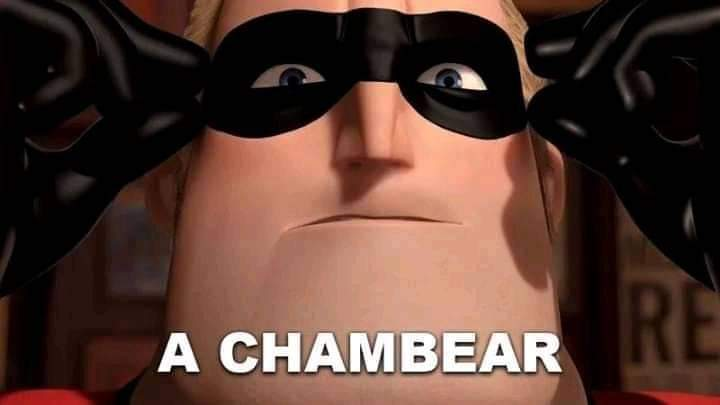

syms t

x = t*cos(2*pi*t)

$$x = t\,\cos\left(2\,\pi \,t\right)$$

y = subs(x,t,t-2)

$$y = \cos\left(2\,\pi \,\left(t-2\right)\right)\,\left(t-2\right)$$

T = [0 3];

subplot(2,1,1)
fplot(x,T)
grid on
legend("x(t)")
subplot(2,1,2)
fplot(y,T,'r')
grid on
legend("y(t)")

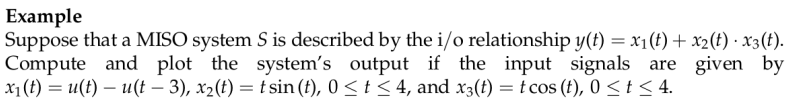

syms t

x1 = heaviside(t)-heaviside(t-3)

$$x1 = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-3\right)$$

x2 = t*sin(t)

$$x2 = t\,\sin\left(t\right)$$

x3 = t*cos(t)

$$x3 = t\,\cos\left(t\right)$$


y = x1+x2*x3

$$y = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-3\right)+t^{2}\,\cos\left(t\right)\,\sin\left(t\right)$$

T = [0 4];

subplot(2,1,1)
fplot(x1,T)
hold on
fplot(x2,T)
fplot(x3,T)
hold off
grid on
legend("x_{1}(t)","x_{2}(t)","x_{3}(t)")


subplot(2,1,2)
fplot(y,T,'r')
grid on
legend("y(t)")



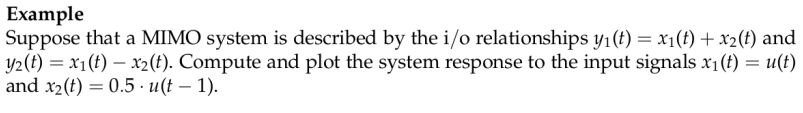

syms  t 

x1 = heaviside(t)

$$x1 = \mathrm{heaviside}\left(t\right)$$

x2 = 0.5*heaviside(t-1)

$$x2 = \frac{\mathrm{heaviside}\left(t-1\right)}{2}$$


y1 = x1+x2

$$y1 = \frac{\mathrm{heaviside}\left(t-1\right)}{2}+\mathrm{heaviside}\left(t\right)$$

y2 = x1-x2

$$y2 = \mathrm{heaviside}\left(t\right)-\frac{\mathrm{heaviside}\left(t-1\right)}{2}$$

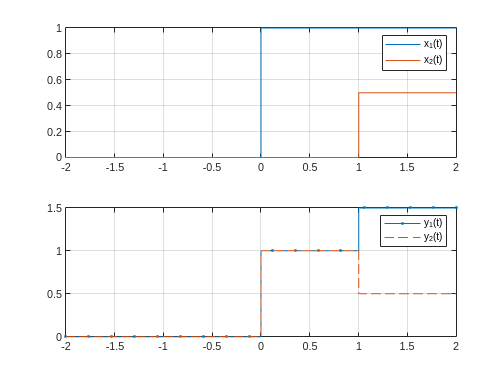


T = [-2 2];

subplot(2,1,1)
fplot(x1,T)
hold on
fplot(x2,T)
hold off
grid on
legend("x_{1}(t)","x_{2}(t)")


subplot(2,1,2)
fplot(y1,T,'.-')
hold on
fplot(y2,T,'--')
hold off
grid on
legend("y_{1}(t)","y_{2}(t)")

## Propiedades

**Causalidad**

syms t

x = heaviside(t) - heaviside(t-1)

$$x = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-1\right)$$

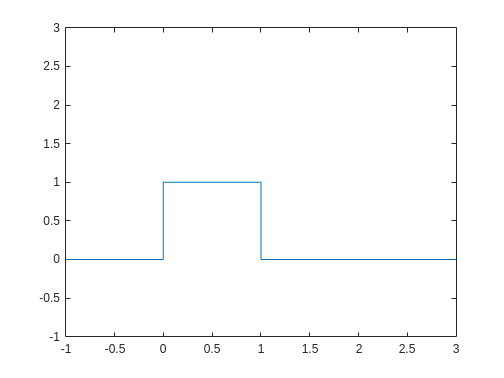

T = [-1 3];
Y = [-1 3];

figure
fplot(x,T)
ylim(Y)

La señal de entrada $x\left(t\right)$ es un pulso cuadrado, que inicia en cero y termina en uno. Si el sistema es causal, esperaría que......; por otra parte, si el sistema no es causal, esperaría que....

y1 = subs(x,t,t+1)

$$y1 = \mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t\right)$$

y2 = subs(x,t,t-1)

$$y2 = \mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t-2\right)$$


T = [-3 3]

T =     -3     3


Y = [-1 3]

Y =     -1     3


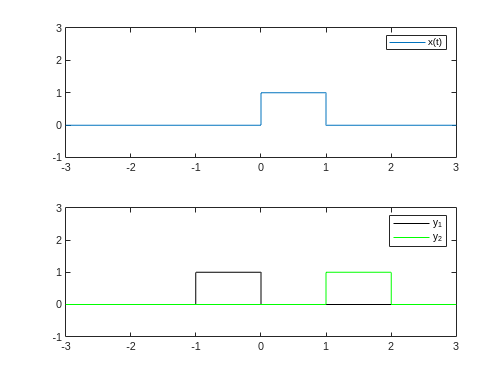


figure
subplot(2,1,1)
fplot(x,T)
ylim(Y)
legend("x(t)")
subplot(2,1,2)
fplot(y1,T,'k')
hold on
fplot(y2,T,'g')
hold off
legend("y_{1}","y_{2}")
ylim(Y)

El sistema $y_1 \left(t\right)$ **no es causal** porque la respuesta comienza antes de que aparezca la señal de entrada $x\left(t\right)$. Por otra parte, $y_{2\;} \left(t\right)$ **es causal** porque la respuesta comienza después de que aparezca la señal de entrada $x\left(t\right)$. 

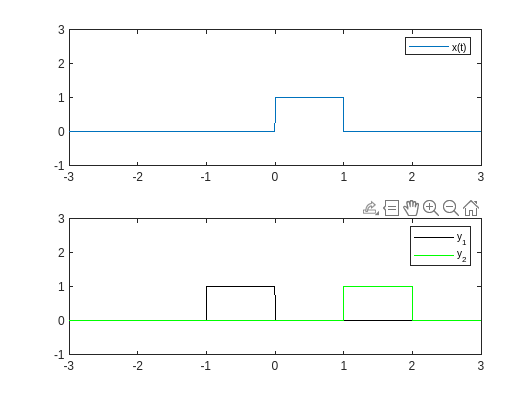

**Memoria**

syms t

x = heaviside(t) - heaviside(t-1)

$$x = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-1\right)$$

T = [-1 3]

T =     -1     3


Y = [-1 5]

Y =     -1     5



y1 = 3*x

$$y1 = 3\,\mathrm{heaviside}\left(t\right)-3\,\mathrm{heaviside}\left(t-1\right)$$

y2 = x+subs(x,t,t-1)

$$y2 = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-2\right)$$

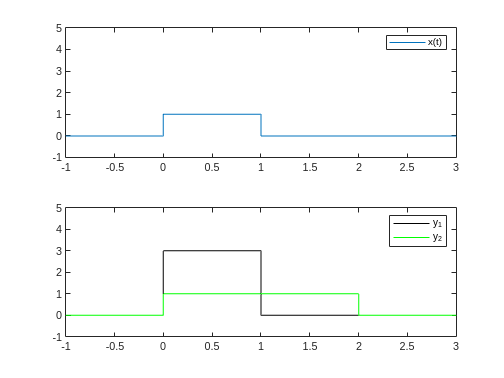


figure
subplot(2,1,1)
fplot(x,T)
ylim(Y)
legend("x(t)")
subplot(2,1,2)
fplot(y1,T,'k')
hold on
fplot(y2,T,'g')
hold off
legend("y_{1}","y_{2}")
ylim(Y)

El sistema $y_2 \left(t\right)$ tiene memoria porque *sigue encendido* a pesar de que $x\left(t\right)$ ya se apagó.

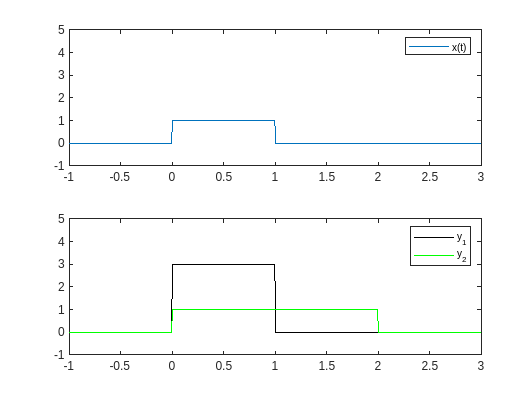

**Linealidad**

clear

syms t s

a1 = 2;
a2 = 5;

x1 = heaviside(t) - heaviside(t-1)

$$x1 = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-1\right)$$

x2 = heaviside(t) - heaviside(t-2)

$$x2 = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-2\right)$$


x_sum = a1*x1 + a2*x2

$$x\_sum = 7\,\mathrm{heaviside}\left(t\right)-5\,\mathrm{heaviside}\left(t-2\right)-2\,\mathrm{heaviside}\left(t-1\right)$$



%Primer sistema
y = 2*s

$$y = 2\,s$$


%Y cerrada
y_c = subs(y,s,x_sum)

$$y\_c = 14\,\mathrm{heaviside}\left(t\right)-10\,\mathrm{heaviside}\left(t-2\right)-4\,\mathrm{heaviside}\left(t-1\right)$$

%Y abierta
y_a = a1*subs(y,s,x1)+a2*subs(y,s,x2)

$$y\_a = 14\,\mathrm{heaviside}\left(t\right)-10\,\mathrm{heaviside}\left(t-2\right)-4\,\mathrm{heaviside}\left(t-1\right)$$

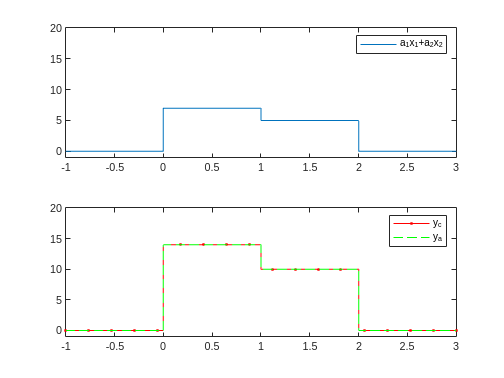



T = [-1 3];
Y = [-1 20];

figure
subplot(2,1,1)
fplot(x_sum,T)
ylim(Y)
legend("a_1x_1+a_2x_2")
subplot(2,1,2)
fplot(y_c,T,'r.-')
hold on
fplot(y_a,T,'g--')
ylim(Y)
hold off
legend("y_c","y_a")




%Segundo sistema
y = s^2

$$y = s^{2}$$


%Y cerrada
y_c = subs(y,s,x_sum)

$$y\_c = {\left(2\,\mathrm{heaviside}\left(t-1\right)+5\,\mathrm{heaviside}\left(t-2\right)-7\,\mathrm{heaviside}\left(t\right)\right)}^{2}$$

%Y abierta
y_a = a1*subs(y,s,x1)+a2*subs(y,s,x2)

$$y\_a = 2\,{\left(\mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t\right)\right)}^{2}+5\,{\left(\mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t\right)\right)}^{2}$$

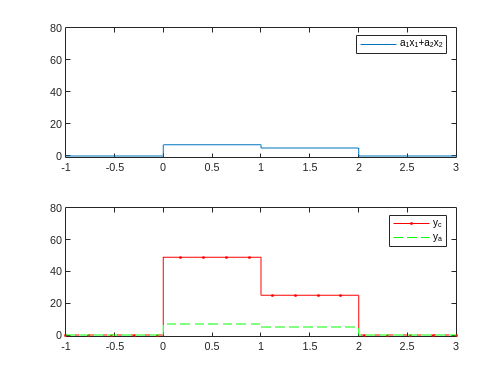



T = [-1 3];
Y = [-1 80];

figure
subplot(2,1,1)
fplot(x_sum,T)
ylim(Y)
legend("a_1x_1+a_2x_2")
subplot(2,1,2)
fplot(y_c,T,'r.-')
hold on
fplot(y_a,T,'g--')
ylim(Y)
hold off
legend("y_c","y_a")

El sistema $y_1 \left(t\right)$ **es lineal**, porque el resultado de $y_1 \left(a_1 x_1 \left(t\right)+a_2 x_2 \left(t\right)\right)$ **es igual** a ${a_1 y}_1 \left(x_1 \left(t\right)\right)+a_2 y_1 \left(x_2 \left(t\right)\right)$, tal como se muestra a continuación.

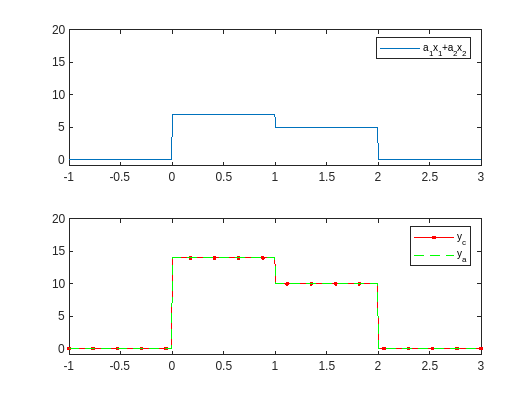

El sistema $y_2 \left(t\right)$ **no es lineal**, porque el resultado de $y_2 \left(a_1 x_1 \left(t\right)+a_2 x_2 \left(t\right)\right)$ **no es igual** a ${a_1 y}_2 \left(x_1 \left(t\right)\right)+a_2 y_2 \left(x_2 \left(t\right)\right)$, tal como se muestra a continuación.

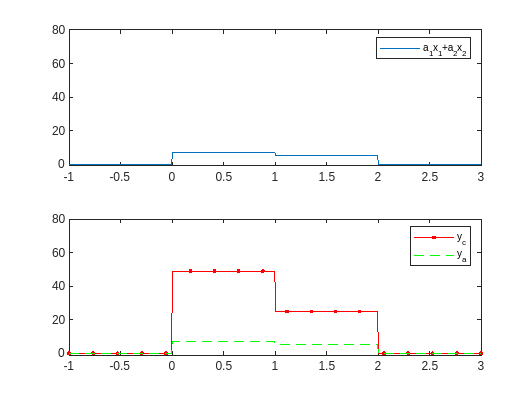

**Invariabilidad temporal**

clear 
syms s t

x = heaviside(t) - heaviside(t-5)

$$x = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-5\right)$$

y = t*exp(-t)*x

$$y = -t\,{\mathrm{e}}^{-t}\,\left(\mathrm{heaviside}\left(t-5\right)-\mathrm{heaviside}\left(t\right)\right)$$


%Tralado en tiempo
t1 = -2;

T = [-4 10];
Y = [-2 2];

%Señal de entrada trasladada en tiempo
x_shifted = subs(x,t,t+t1)

$$x\_shifted = \mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t-7\right)$$

%Salida del sistema alimentada con una señal trasladada en tiempo
y_original = subs(y,x,x_shifted)

$$y\_original = t\,{\mathrm{e}}^{-t}\,\left(\mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t-7\right)\right)$$

%Salida del sistema traladado en tiempo, alimentado con señal original
y_shifted = subs(y,t,t+1)

$$y\_shifted = {\mathrm{e}}^{-t-1}\,\left(\mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-4\right)\right)\,\left(t+1\right)$$

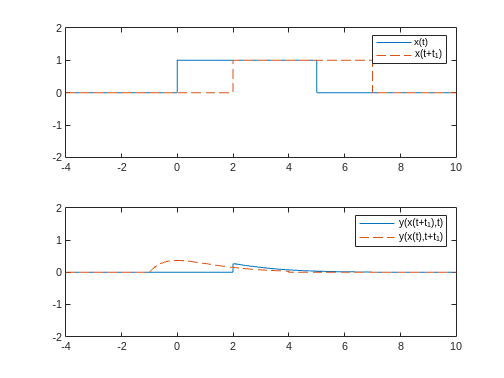



figure
subplot(2,1,1)
fplot(x,T)
hold on
fplot(x_shifted,T,'--')
hold off
ylim(Y)
legend("x(t)","x(t+t_1)")
subplot(2,1,2)
fplot(y_original,T)
hold on
fplot(y_shifted,T,'--')
ylim(Y)
hold off
legend("y(x(t+t_1),t)","y(x(t),t+t_1)")

El sistema $y\left(t\right)$ **no es invariante en el tiempo** porque (**la forma de) la respuesta del sistema cambia** cuando se alimenta con la señal $x\left(t\right)$ a tiempos distintos

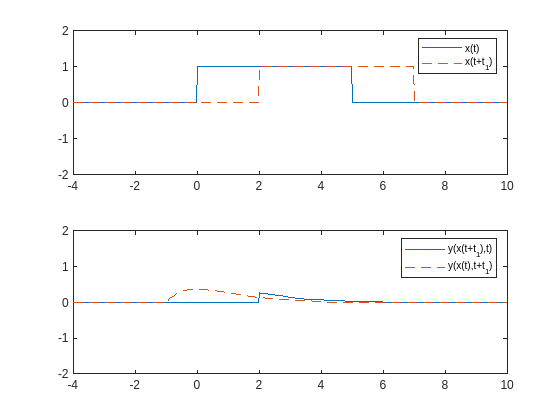

clear 
syms s t

x = cos(t)*(heaviside(t) - heaviside(t-10))

$$x = -\cos\left(t\right)\,\left(\mathrm{heaviside}\left(t-10\right)-\mathrm{heaviside}\left(t\right)\right)$$

y = 1-2*subs(x,t,t-1)

$$y = 1-2\,\cos\left(t-1\right)\,\left(\mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t-11\right)\right)$$


%Tralado en tiempo
t1 = -2;

T = [-2 15];
Y = [-10 10];

%Señal de entrada trasladada en tiempo
x_shifted = subs(x,t,t+t1)

$$x\_shifted = \cos\left(t-2\right)\,\left(\mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t-12\right)\right)$$

%Salida del sistema alimentada con una señal trasladada en tiempo
y_original = subs(y,x,x_shifted)

$$y\_original = 1-2\,\cos\left(t-1\right)\,\left(\mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t-11\right)\right)$$

%Salida del sistema traladado en tiempo, alimentado con señal original
y_shifted = subs(y,t,t+1)

$$y\_shifted = 2\,\cos\left(t\right)\,\left(\mathrm{heaviside}\left(t-10\right)-\mathrm{heaviside}\left(t\right)\right)+1$$

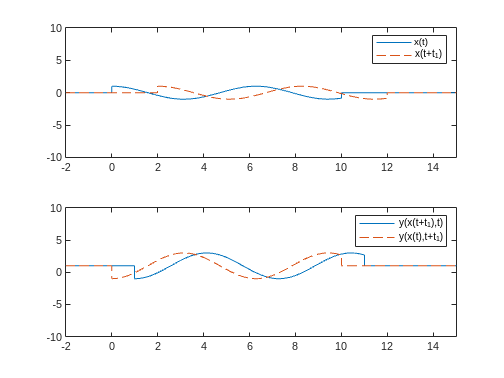



figure
subplot(2,1,1)
fplot(x,T)
hold on
fplot(x_shifted,T,'--')
hold off
ylim(Y)
legend("x(t)","x(t+t_1)")
subplot(2,1,2)
fplot(y_original,T)
hold on
fplot(y_shifted,T,'--')
ylim(Y)
hold off
legend("y(x(t+t_1),t)","y(x(t),t+t_1)")

El sistema $y\left(t\right)$ **es invariante en el tiempo** porque (**la forma de) la respuesta del sistema no cambia** cuando se alimenta con la señal $x\left(t\right)$ a tiempos distintos

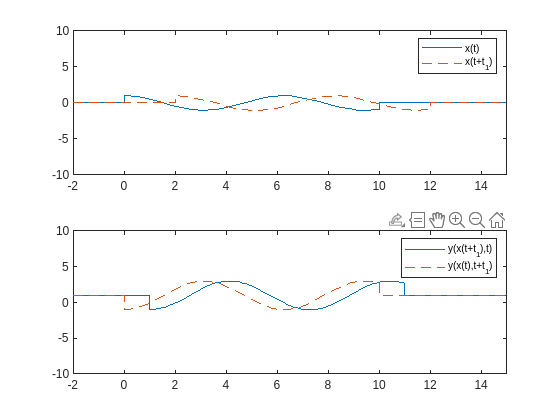

**Invertibilidad**

clear 
syms s t

x = 2*t

$$x = 2\,t$$


y1 = 3*x

$$y1 = 6\,t$$

y2 = x^2

$$y2 = 4\,t^{2}$$


T = [-5 5];
Y = [-10 10];

%Despejo calcular "la función inversa"
y1_inv = s/3

$$y1\_inv = \frac{s}{3}$$

y2_inv = sqrt(s)

$$y2\_inv = \sqrt{s}$$


%Respuesta de la funcion inversa
x1_inv = subs(y1_inv,s,y1)

$$x1\_inv = 2\,t$$

x2_inv = subs(y2_inv,s,y2)

$$x2\_inv = \sqrt{4\,t^{2}}$$

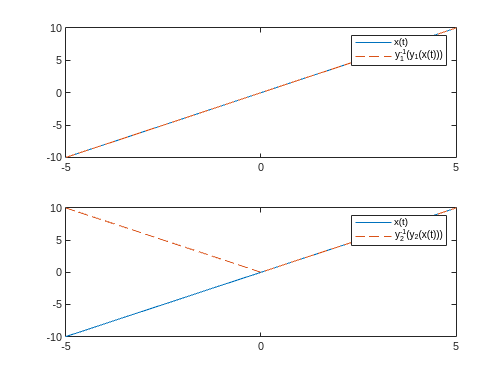


figure
subplot(2,1,1)
fplot(x,T)
hold on
fplot(x1_inv,T,'--')
hold off
legend("x(t)","y^{-1}_1(y_1(x(t)))")
subplot(2,1,2)
fplot(x,T)
hold on
fplot(x2_inv,T,'--')
hold off
legend("x(t)","y^{-1}_2(y_2(x(t)))")

El sistema $y_1 \left(t\right)$ es invertible, mientras que $y_2 \left(t\right)$ no lo es.

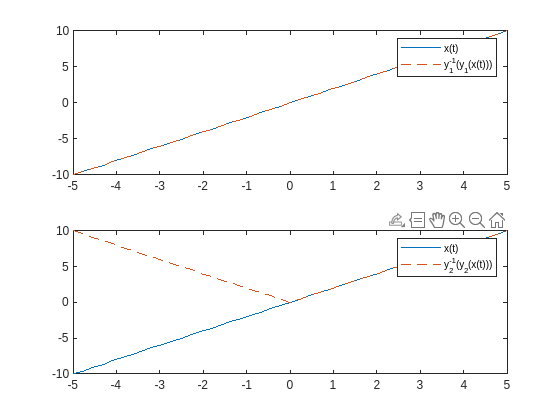

**Estabilidad**

clear 

syms s t 
x = cos(2*pi*t)

$$x = \cos\left(2\,\pi \,t\right)$$

y1 = x^2

$$y1 = {\cos\left(2\,\pi \,t\right)}^{2}$$

y2 = t*x

$$y2 = t\,\cos\left(2\,\pi \,t\right)$$

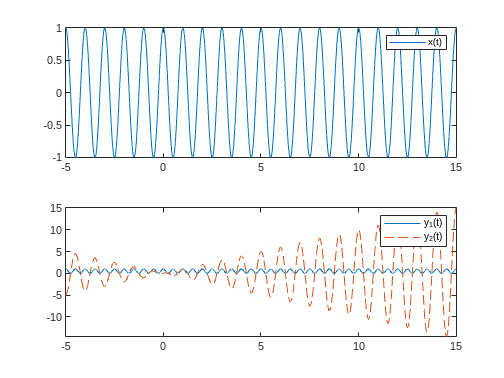


T = [-5 15];

figure
subplot(2,1,1)
fplot(x,T)
legend("x(t)")
subplot(2,1,2)
fplot(y1,T)
hold on
fplot(y2,T,'--')
hold off
legend("y_1(t)","y_2(t)")

El sistema $y_1 \left(t\right)$ es **estable** porque, dada una entrada $x\left(t\right)$ acotada, la salida es** visiblemente acotada**; por otra parte $y_2 \left(t\right)$, bajo las mismas condiciones, visiblemente **diverge en un tiempo grande**, por lo que **es inestable**.

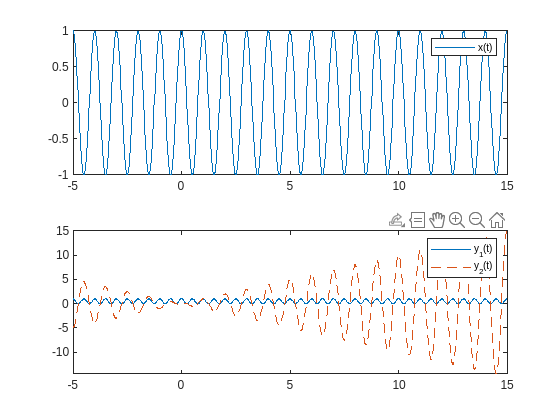

## Final

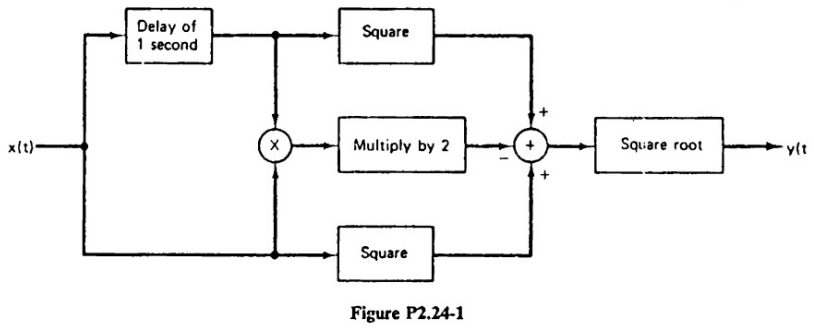

clear
syms s t

x = cos(t)*(heaviside(t)-heaviside(t-10))

$$x = -\cos\left(t\right)\,\left(\mathrm{heaviside}\left(t-10\right)-\mathrm{heaviside}\left(t\right)\right)$$


%a
x_d = subs(x,t,t+1)

$$x\_d = \cos\left(t+1\right)\,\left(\mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-9\right)\right)$$


y = sqrt(x_d^2-2*(x_d*x)+x^2)

$$y = \sqrt{{\cos\left(t+1\right)}^{2}\,{\left(\mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-9\right)\right)}^{2}+{\cos\left(t\right)}^{2}\,{\left(\mathrm{heaviside}\left(t-10\right)-\mathrm{heaviside}\left(t\right)\right)}^{2}+2\,\cos\left(t+1\right)\,\cos\left(t\right)\,\left(\mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-9\right)\right)\,\left(\mathrm{heaviside}\left(t-10\right)-\mathrm{heaviside}\left(t\right)\right)}$$


%b
%La última etapa es una raiz cuadrada, entonces no es lineal.


%c
%Tralado en tiempo
t1 = -2;

T = [-5 15];
Y = [-4 4];

%Señal de entrada trasladada en tiempo
x_shifted = subs(x,t,t+t1)

$$x\_shifted = \cos\left(t-2\right)\,\left(\mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t-12\right)\right)$$

%Salida del sistema alimentada con una señal trasladada en tiempo
y_original = subs(y,x,x_shifted)

$$y\_original = \sqrt{{\cos\left(t+1\right)}^{2}\,{\left(\mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-9\right)\right)}^{2}+{\cos\left(t\right)}^{2}\,{\left(\mathrm{heaviside}\left(t-10\right)-\mathrm{heaviside}\left(t\right)\right)}^{2}+2\,\cos\left(t+1\right)\,\cos\left(t\right)\,\left(\mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-9\right)\right)\,\left(\mathrm{heaviside}\left(t-10\right)-\mathrm{heaviside}\left(t\right)\right)}$$

%Salida del sistema traladado en tiempo, alimentado con señal original
y_shifted = subs(y,t,t+1)

$$y\_shifted = \begin{array}{l} \sqrt{{\cos\left(t+1\right)}^{2}\,{\sigma_{2}}^{2}+{\cos\left(t+2\right)}^{2}\,{\sigma_{1}}^{2}-2\,\cos\left(t+1\right)\,\cos\left(t+2\right)\,\sigma_{2}\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{heaviside}\left(t+2\right)-\mathrm{heaviside}\left(t-8\right)\\ \sigma_{2}=\mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-9\right) \end{array}$$

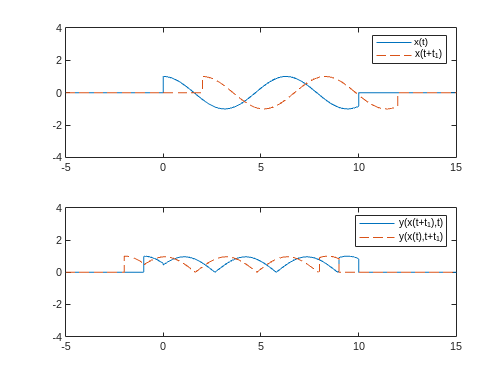



figure
subplot(2,1,1)
fplot(x,T)
hold on
fplot(x_shifted,T,'--')
hold off
ylim(Y)
legend("x(t)","x(t+t_1)")
subplot(2,1,2)
fplot(y_original,T)
hold on
fplot(y_shifted,T,'--')
ylim(Y)
hold off
legend("y(x(t+t_1),t)","y(x(t),t+t_1)")

Es invariable en el tiempo